# Explore Covid-19 Cases by Location

We have data by state and county, lets explore.

## Explore cases by location

### Import data for states and counties

Use the function provided to read the data files containing locations and combine with the 'live' data files.

usstates = ReadCovidData("us-states.csv");
uscounties = ReadCovidData("us-counties.csv");
head(usstates)

ans = 8×4 timetable
       date         state       fips    cases    deaths
    __________    __________    ____    _____    ______
    2020-01-21    Washington     53       1        0   
    2020-01-22    Washington     53       1        0   
    2020-01-23    Washington     53       1        0   
    2020-01-24    Illinois       17       1        0   
    2020-01-24    Washington     53       1        0   
    2020-01-25    California      6       1        0   
    2020-01-25    Illinois       17       1        0   
    2020-01-25    Washington     53       1        0   

Save the data before we move on. 

save Data/usDataLocations.mat uscounties usstates 

It could be challenging to analyze in this way. Let's do some rearranging or grouped calculations first to help us analyze in various ways.

Make the rows unique dates and states are variables. Use the Unstack Live Editor Task to explore and perform this easily

% Unstack variables
statesByTime = unstack(usstates,'cases','state',...
    'AggregationFunction',@(x)x(~isempty(x)),'VariableNamingRule','preserve');

Get the state names as a variable for future reference.

statenames = statesByTime.Properties.VariableNames;

We can also get the deaths by time using the code generated from the Live Task. Let's focus on the cases for now.

### Compare locations over time

There are many ways to visualize. Start by visualize all as line plots (include first few to make it more reasonable to consume)

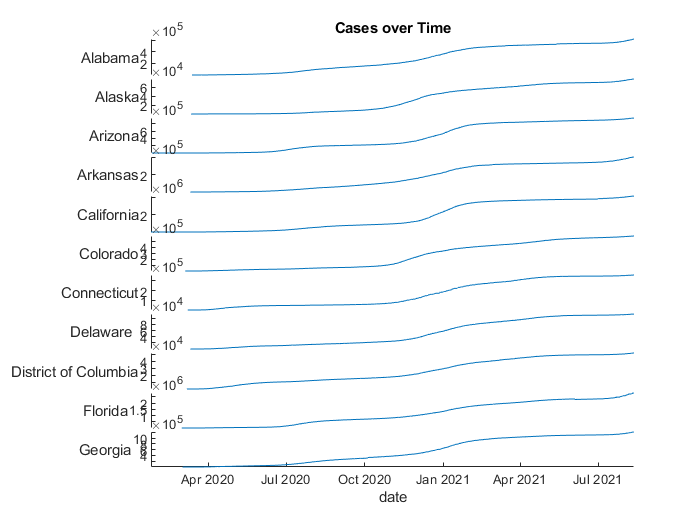

stackedplot(statesByTime(:,1:11))
title("Cases over Time")

There are NaN for dates where no data were reported in the beginning, we could fill with zero for convenience or leave it alone for now.

Explore visualizations over time and group.

Use a `heatmap` (or matrix visualization like `imagesc`) to try to visualize better all at once. 

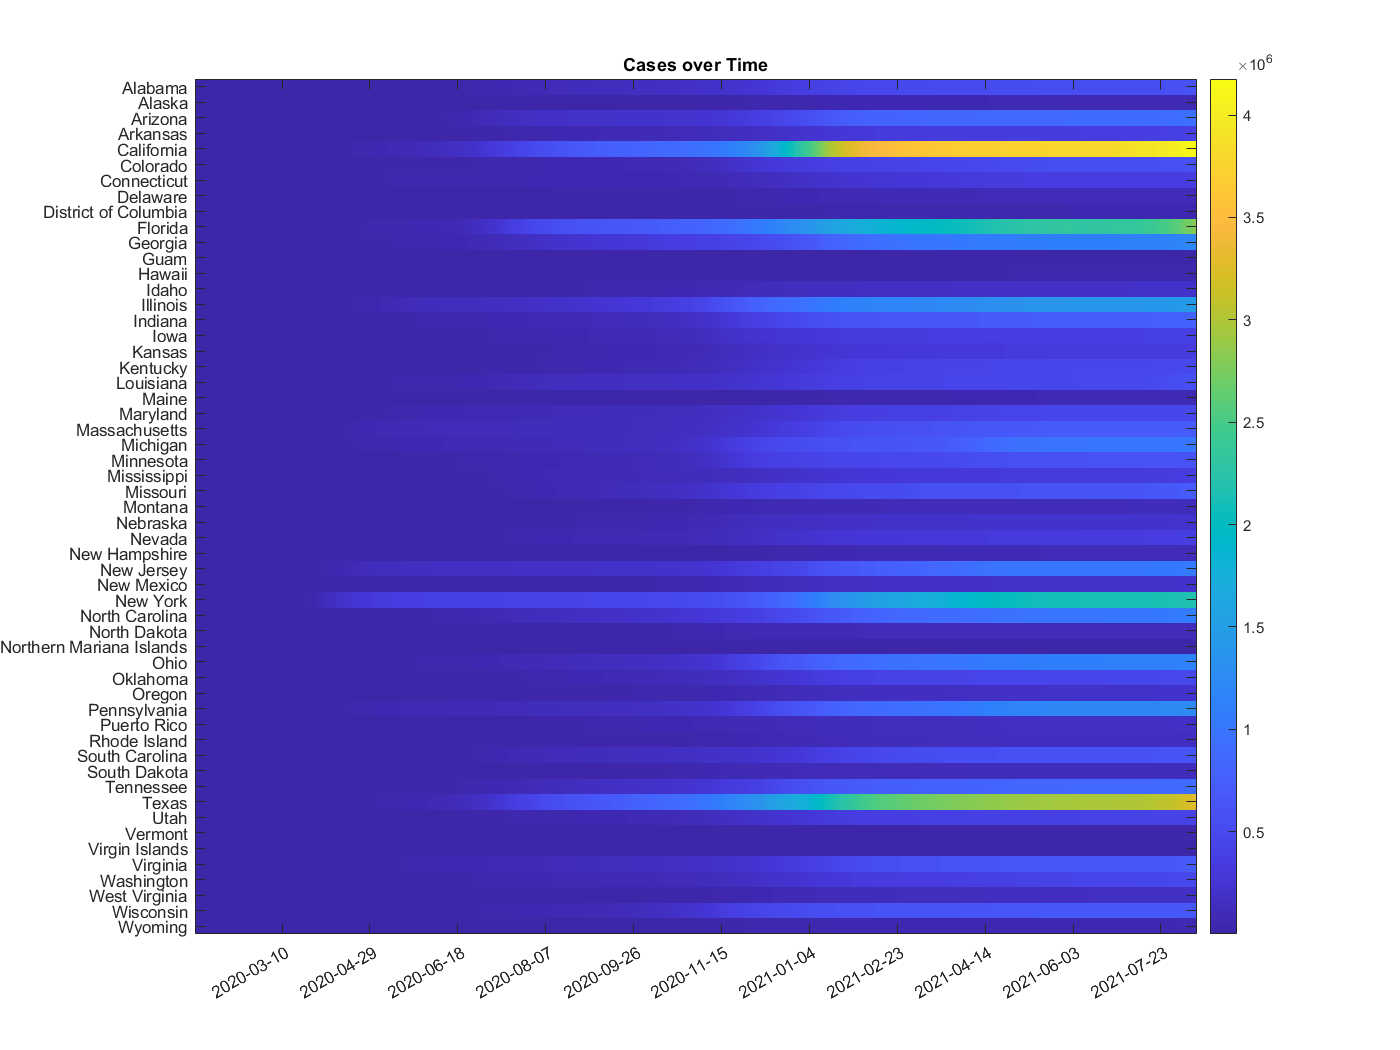

bigFigure;
imagesc(statesByTime.Variables')      
labelHeatmapOverTime(statesByTime,statenames)

Try normalizing the data (scaling to unit mean and standard deviation) for comparison.

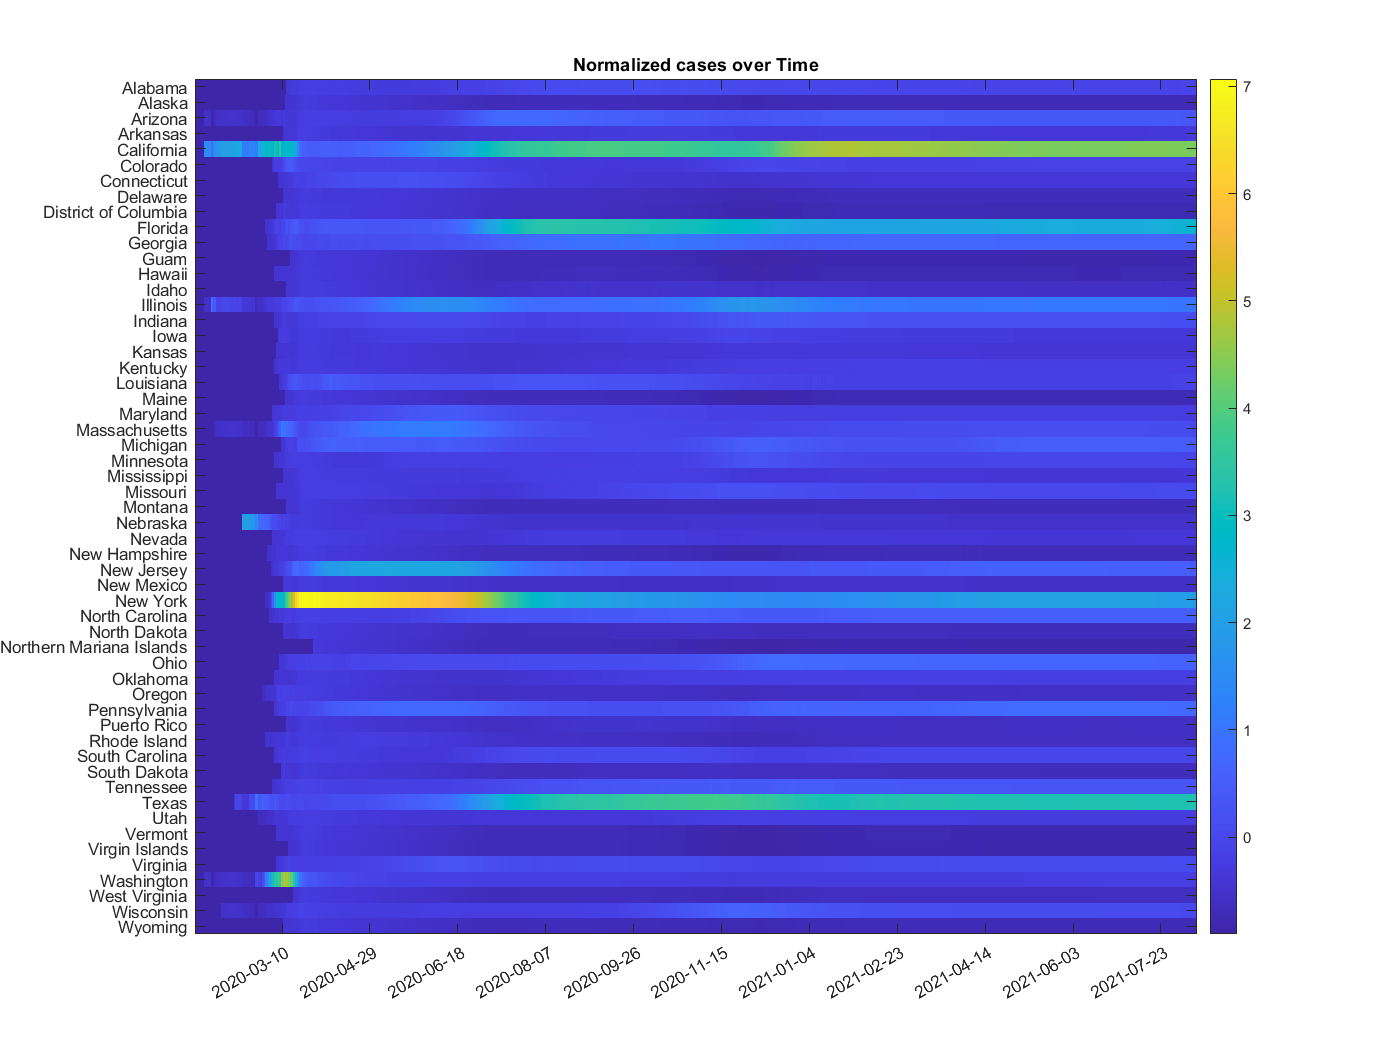

imagesc(normalize(statesByTime.Variables'))
labelHeatmapOverTime(statesByTime,statenames)
title("Normalized cases over Time")

### Which locations have the most cases?

Get most recent data by state. Use `groupsummary` for calculations by category and date component. Calculations include defaults, but lets use the user-defined function `lastValueCalc.m`

maxByState = groupsummary(usstates,"state","max",...
    ["cases","deaths"]);
recentByState = groupsummary(usstates,"state", @lastValueCalc,...
    ["cases","deaths"]);
recentByState.Properties.VariableNames = erase(recentByState.Properties.VariableNames,"fun1_")

recentByState = 55×4 table
           state            GroupCount      cases       deaths
    ____________________    __________    __________    ______
    Alabama                    518        6.2392e+05    11724 
    Alaska                     519             78415      383 
    Arizona                    565        9.5577e+05    18412 
    Arkansas                   520        4.1083e+05     6366 
    California                 566        4.1761e+06    64518 
    Colorado                   526        5.8978e+05     7170 
    Connecticut                523        3.6055e+05     8297 
    Delaware                   520        1.1358e+05     1837 
    District of Columbia       524             51853     1149 
    Florida                    530        2.8068e+06    40171 
    Georgia                    529        1.2109e+06    21183 
    Guam          

Find states with the most cases currently. 

n = 10;
% topkrows(recentByState,n,"cases")

Create a function `topkLocations`  to do this and visualize (to repeat the process)

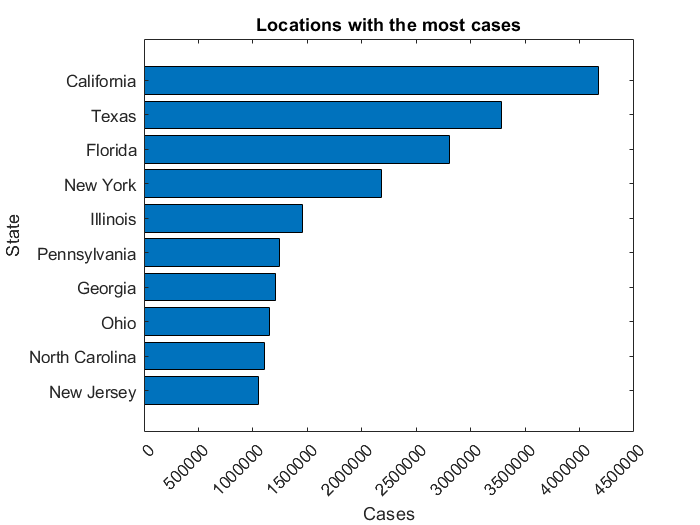

figure
tk = topkLocations(recentByState,n,"cases");
tstr = "Locations with the most cases";
updatePlotLabels(gca,"Cases","State",tstr,"x")

### How have these changed over time?

Use the top locations as calculated above to explore how they've changed over time. Lets try to visualize on separate axes, the same axes, and also see how the top locations have changed for comparison.

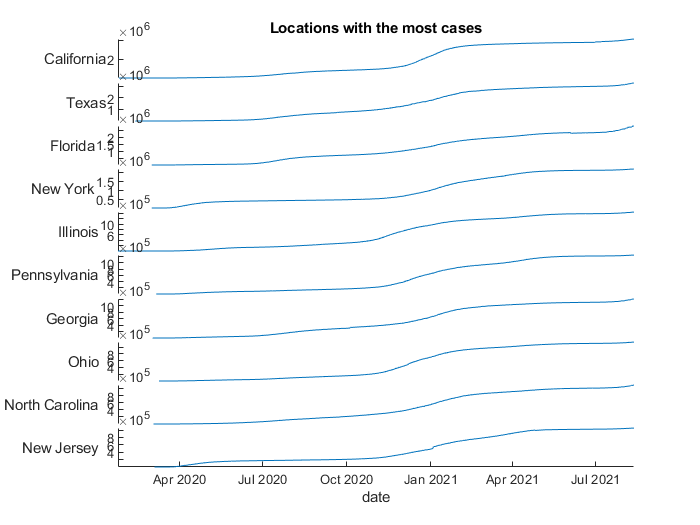

vars = string(tk.state);
stackedplot(statesByTime(:,vars))
title(tstr)

Visualize on the same axes for comparison. 

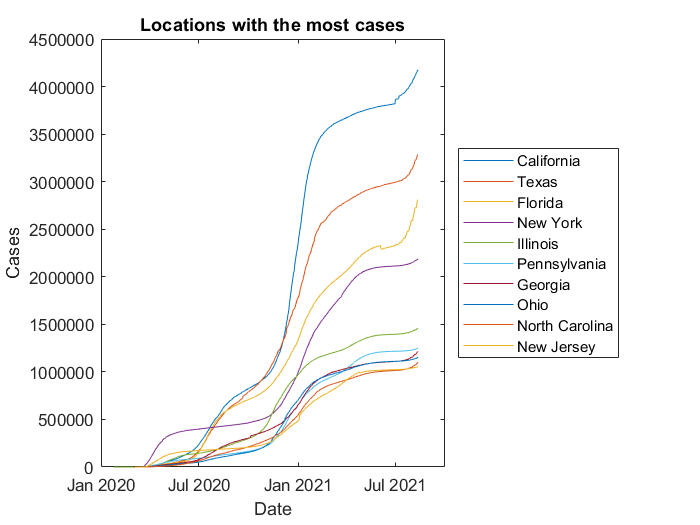

plot(statesByTime.date,statesByTime{:,vars})
legend(vars,"Location","eastoutside")
a = gca;
updatePlotLabels(a,"Date","Cases",tstr,"y")

Update the colors so they are not repeating (7 before repeating color order). Here, we can easily use a colormap with 10 values so its pretty in order :)

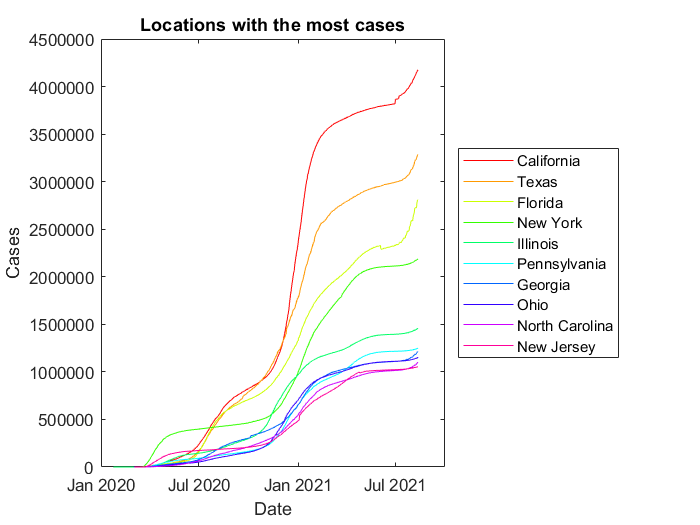

a.ColorOrder = hsv(10);

#### How do the top states change over time?

Use the bar plot from above in an animation (user defined function)

% overTimeGif(usstates,"cases","bar",...
%     "Top Covid-19 Cases by Location",10,"statesBarOverTime.gif")

Save what we've got so far.

% save Data/usDataLocations statesByTime recentByState -append

## Scale by population

We have data by county in each state, but the case numbers could be misleading if the population is very high. 

Include population by county from the US census

This script imports and joins the population data to the cases and deaths by county: [IncludePopulation.mlx](matlab:open('./IncludePopulation.mlx'))    

load countyInfo.mat countyInfo

Do the same grouped calculation as above for counties to get the most recent value. Include the states since these are repeated.

recentByCounty = groupsummary(uscounties,["county","state","fips"], @lastValueCalc,...
    ["cases","deaths"]); 
recentByCounty.Properties.VariableNames = erase(recentByCounty.Properties.VariableNames,"fun1_");

Combine this with county info to get totals, population

% recentByCounty.fips = categorical(recentByCounty.fips);

% Join tables
totalcounty = outerjoin(recentByCounty,countyInfo,'Type','left','Keys',...
    {'fips','county','state'},'MergeKeys',true)

totalcounty = 3276×16 table
     county      state     fips    GroupCount    cases    deaths    abbrev    POPESTIMATE2019    DEATHS2019      LON       LAT      NEVER    RARELY    SOMETIMES    FREQUENTLY    ALWAYS
    ________    _______    ____    __________    _____    ______    ______    _______________    __________    _______    ______    _____    ______    _________    __________    ______
    Autauga     Alabama    1001       507         7890    

Calculate cases and deaths by population.

totalcounty.casesbypop = totalcounty.cases./totalcounty.POPESTIMATE2019*100;
totalcounty.deathsbypop = totalcounty.deaths./totalcounty.POPESTIMATE2019*100;

Add the bar over time by population to the most current cases to compare.

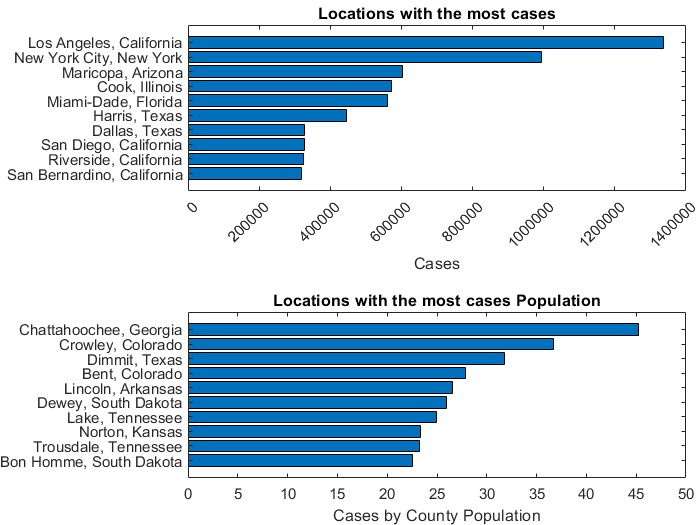

figure
tiledlayout(2,1,"Padding","none");
nexttile;
tk = topkLocations(recentByCounty,n,"cases");
updatePlotLabels(gca,"Cases","",tstr,"x")
nexttile;
tp = topkLocations(totalcounty,n,"casesbypop");
updatePlotLabels(gca,"Cases by County Population","",...
    tstr+ " Population")

### Visualizations

### Map of cases per county

Let's look at data by county on a map using latitude longitude

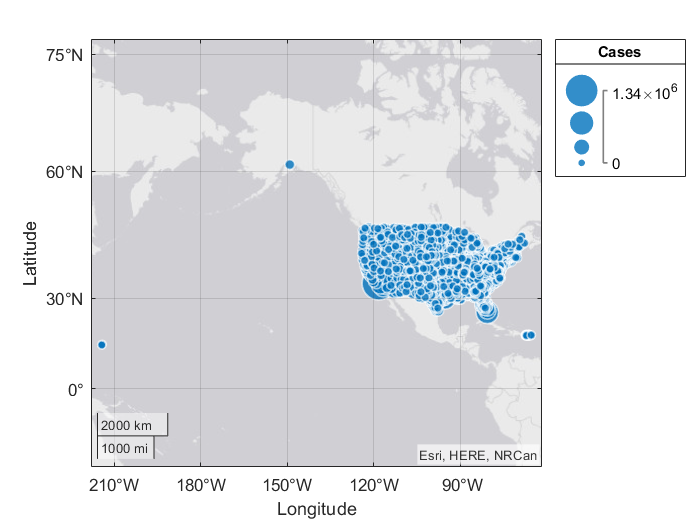

figure
geobubble(totalcounty.LAT,totalcounty.LON,totalcounty.cases,...
    "SizeLegendTitle","Cases");

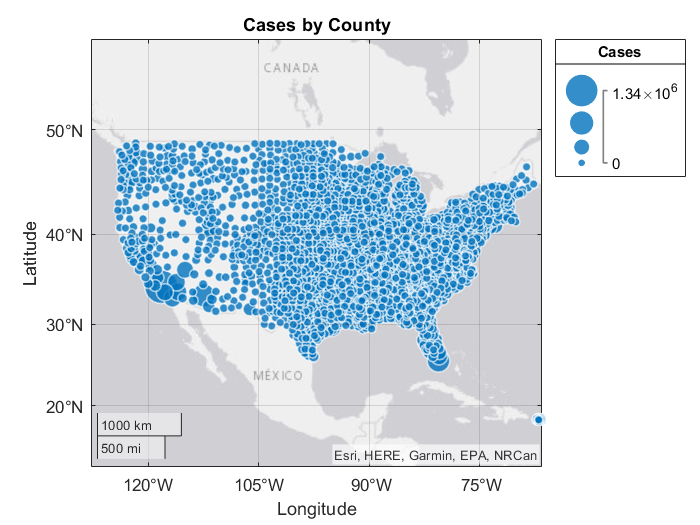

% zoom and pan in the plot and update code for zoomed area
geolimits([16.0 55.0],[-127.8 -66.5])
tstr = "Cases by County";
title(tstr)

Recreate the map visual using cases by population instead.

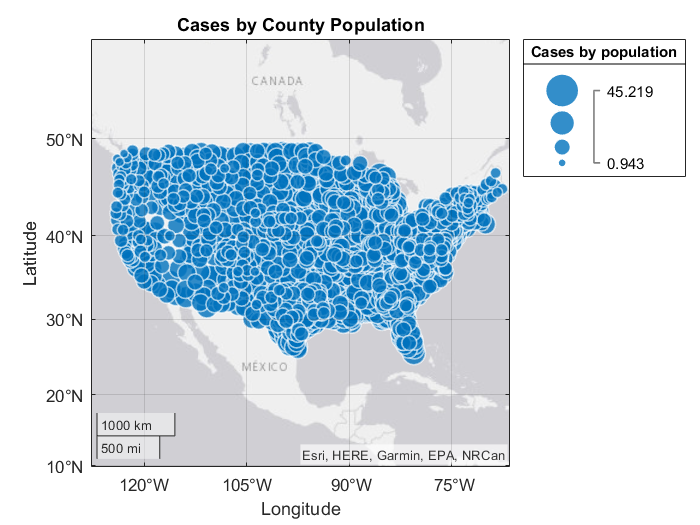

geobubble(totalcounty.LAT,totalcounty.LON,totalcounty.casesbypop,...
    "SizeLegendTitle","Cases by population");
geolimits([16.0 55.0],[-127.8 -66.5])
title(tstr + " Population")

We can explore other visuals to see any trends on the map.

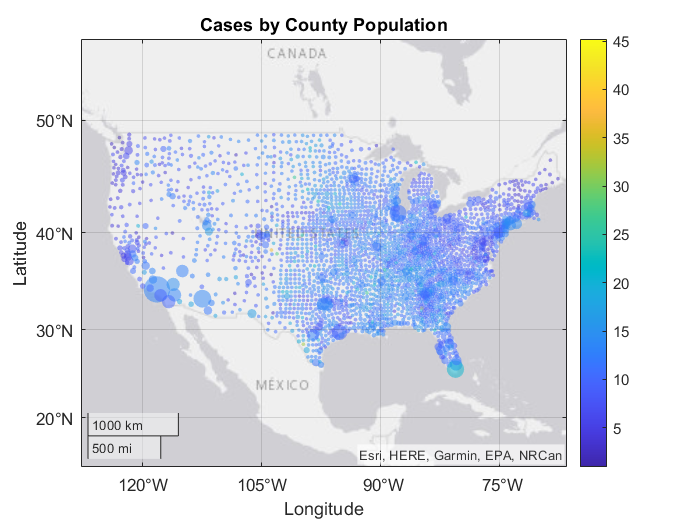

r = rescale(totalcounty.cases,5,250);
geoscatter(totalcounty.LAT,totalcounty.LON,r,totalcounty.casesbypop,'filled',...
    "MarkerFaceAlpha",0.5);
geolimits([16.0 55.0],[-127.8 -66.5])
colorbar
title(tstr + " Population")

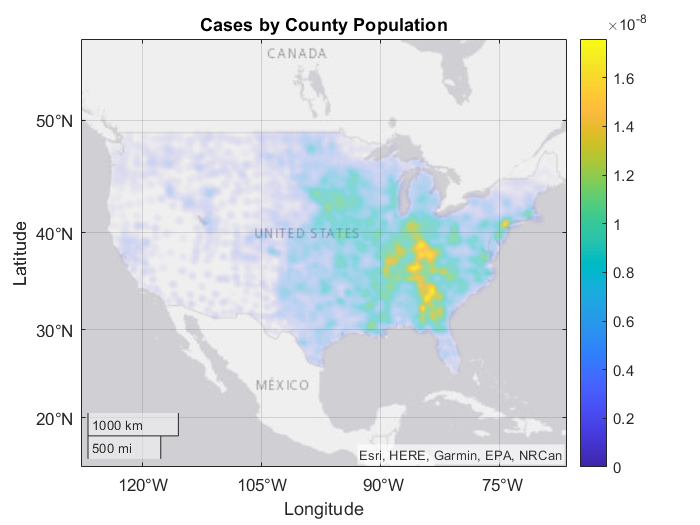

geodensityplot(totalcounty.LAT,totalcounty.LON,totalcounty.casesbypop,...
    "FaceColor","interp","FaceAlpha","interp");
geolimits([16.0 55.0],[-127.8 -66.5])
colorbar
title(tstr + " Population")

How could we include time in the map vis? We can do the same approach as before and plot each frame, save gif. We could also do this weekly instead of daily, split by time.

(Do this from the command line)

% overTimeGif(totalcounty,["cases","casesbypop"],"map",...
%   "Top Covid-19 Cases by Location and Population",10,"mapgif.gif");

Save current population data

save Data/mergedCountyData totalcounty recentByCounty

## TODO: bars for different timelines, surges over past month

## Include mask usage survey data

Next, we'll include mask usage survey data by county. We can explore, see if there seems to be an effect on number of cases.

edit MaskUsageDataAnalysis.mlx

**Helper functions**

function labelHeatmapOverTime(statesByTime,statenames)
xt = xticks;
xticklabels(string(statesByTime.date(xt)))
yticks(1:55)
yticklabels(statenames)
colorbar
title("Cases over Time")

end